# K-means, Fuzzy C-Means and SOM for clustering

clc; clear;
close all;
warning off all;

Archivo data

archivo_csv = 'data.csv';
datos = readtable(archivo_csv);
% disp(datos(1:10,:));
datos = removevars(datos, {'subject', 'Activity'});

Revolviendo datos

stir = size(datos,1);
[dummy, rnd] = sort(rand(stir, 1));
datos = datos(rnd, :);
disp(datos(1:10,:));

    tBodyAcc_mean___X    tBodyAcc_mean___Y    tBodyAcc_mean___Z    tBodyAcc_std___X    tBodyAcc_std___Y    tBodyAcc_std___Z    tBodyAcc_mad___X    tBodyAcc_mad___Y    tBodyAcc_mad___Z    tBodyAcc_max___X    tBodyAcc_max___Y    tBodyAcc_max___Z    tBodyAcc_min___X    tBodyAcc_min___Y    tBodyAcc_min___Z    tBodyAcc_sma__    tBodyAcc_energy___X    tBodyAcc_energy___Y    tBodyAcc_energy___Z    tBodyAcc_iqr___X    tBodyAcc_iqr___Y    tBodyAcc_iqr___Z    tBodyAcc_entropy___X    tBodyAcc_entropy___Y    tBodyAcc_entropy___Z    tBodyAcc_arCoeff___X_1    

datos = table2array(datos);

## K-means

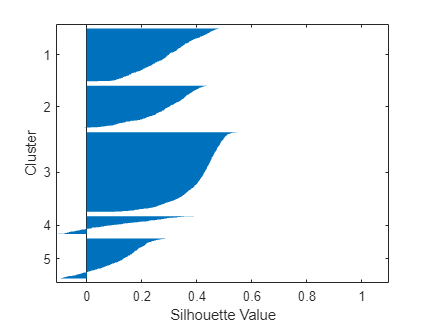

[silhouetteK1, labelsK1] = Kmeans(datos, 5);

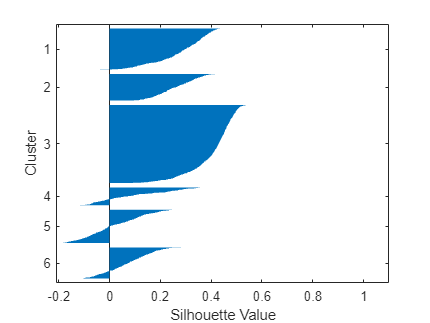

[silhouetteK2, labelsK2] = Kmeans(datos, 6);

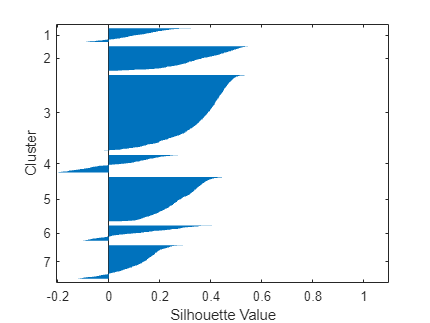

[silhouetteK3, labelsK3] = Kmeans(datos, 7);

Resultados

numClustersK = ["5"; "6"; "7"];

res_Kmeans = [silhouetteK1, silhouetteK2, silhouetteK3];

resultadosK = table(numClustersK, res_Kmeans');
resultadosK.Properties.VariableNames = {'Número de clusters', 'Silhouette score',};

disp(resultadosK);

    Número de clusters    Silhouette score
    __________________    ________________

           "5"                0.28472     
           "6"                0.23954     
           "7"                0.24783     



## Fuzzy C-Means

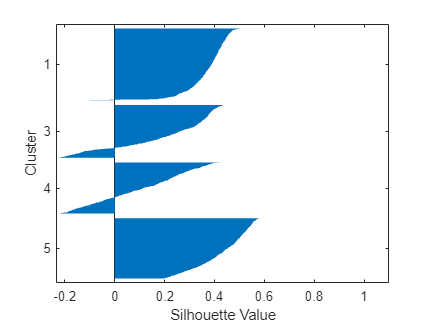

[silhouetteC1, labelsC1] = Cmeans(datos, 5, 2);

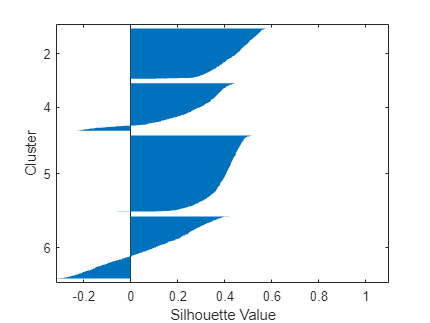

[silhouetteC2, labelsC2] = Cmeans(datos, 6, 2);

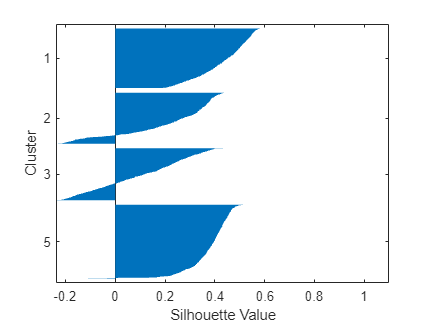

[silhouetteC3, labelsC3] = Cmeans(datos, 7, 2);

Resultados

numClustersC = ["5"; "6"; "7"];

res_FCM = [silhouetteC1, silhouetteC2, silhouetteC3];

resultadosF = table(numClustersC, res_FCM');
resultadosF.Properties.VariableNames = {'Número de clusters', 'Silhouette score',};

disp(resultadosF);

    Número de clusters    Silhouette score
    __________________    ________________

           "5"                0.29122     
           "6"                0.28896     
           "7"                0.29602     



## SOM

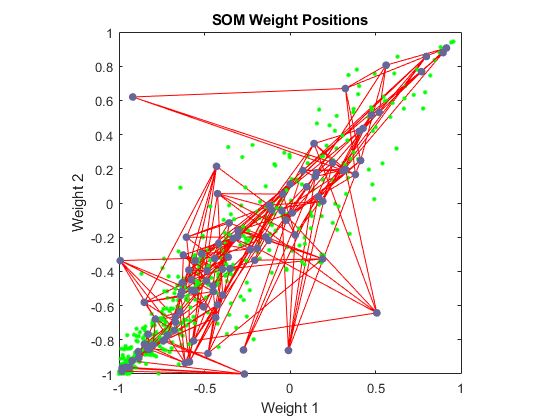

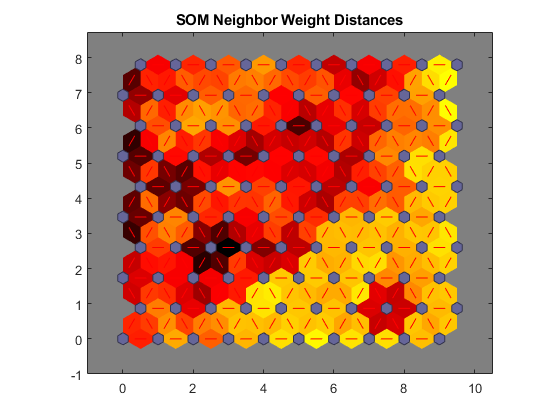

cluster1 = SOM(datos, 10, 10, 'hextop', 1000);

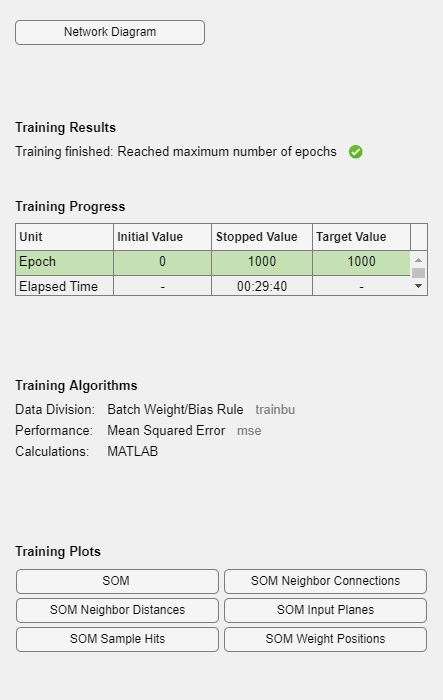

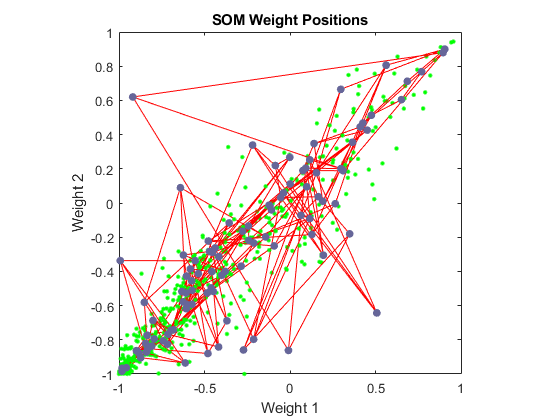

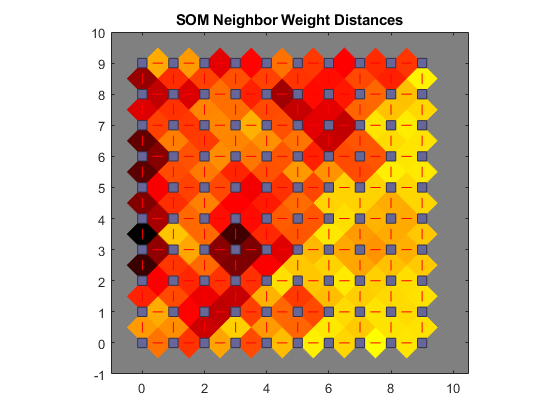

scoreInd1 = silhouette(datos', cluster1);
score1 = mean(scoreInd1);

cluster2 = SOM(datos, 10, 10, 'gridtop', 1000); 

scoreInd2 = silhouette(datos', cluster2);
score2 = mean(scoreInd2);

Resultados

numClustersS = ["hextop"; "gridtop"];

res_SOM = [score1, score2];

resultadosS = table(numClustersS, res_SOM');
resultadosS.Properties.VariableNames = {'Topología', 'Silhouette score',};

disp(resultadosS);

    Topología    Silhouette score
    _________    ________________

    "hextop"         0.31619     
    "gridtop"        0.32954     

